# Mesh Generation with MATLAB Partial Differential Equation Toolbox

## Geometry generation with delaunayTriangulation and isInterior

clear;
r=0.45;
theta=pi:-pi/10:-pi/2;
%theta=pi:-pi/20:-pi/2;
%theta=pi:-pi/30:-pi/2;

nodes_geo = [-0.5 -0.5 0.5 0.5  r*cos(theta),-r;  
         0.5 -0.5 -0.5 0.5  r*sin(theta),-r];

sz=length(theta); szt=4+sz+1;
edges_geo =[1:szt;
  2:4,1,6:szt,5];

DT = delaunayTriangulation(nodes_geo', edges_geo');
TF = isInterior(DT);
elements_geo=DT(TF,:)';

% TR = triangulation(elements_geo',nodes_geo');
% stlwrite(TR,'SquareLargeHole.stl');

## Figure Trianglated Geometry

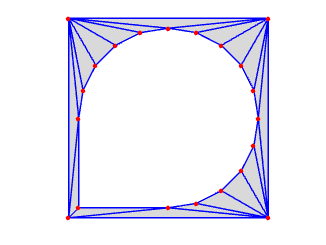

figure; 
patch('Faces',elements_geo','Vertices',nodes_geo','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');
% hold on
% plot([nodes(1, edges(1,:));nodes(1, edges(2,:))] , ...
%      [nodes(2, edges(1,:)); nodes(2, edges(2,:))], ...
%      Color = 'r', Marker='.',MarkerEdgeColor='b', MarkerSize = 8);

hold on
plot(nodes_geo(1, :), nodes_geo(2, :), 'r.', MarkerSize = 10);

% hold on
% text(nodes(1,:),nodes(2,:), 'n' + string(1:size(nodes,2)));
% hold on
% text((nodes(1, edges(1,:)) + nodes(1, edges(2,:)))/2, ...
%      (nodes(2, edges(1,:)) + nodes(2, edges(2,:)))/2, ...
%     'e' + string(1:size(edges,2)));

axis equal off

%exportgraphics(gca,'SquareLargeHole-Geo.pdf','ContentType','vector');

## Geometry from Triangulated Mesh

Create a PDE model.

model = createpde;

Geometry from Triangulated Mesh

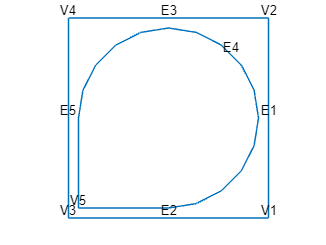

geometryFromMesh(model,nodes_geo,elements_geo);
figure; 
pdegplot(model,VertexLabels = "on",EdgeLabels = "on");
axis equal off

## Example 1: default name-value arguments

### Mesh generation

mesh = generateMesh(model, GeometricOrder = "linear");
nodes = mesh.Nodes; elements =mesh.Elements;

### Figure mesh

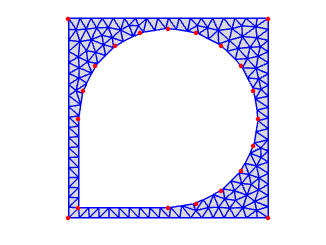

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on
plot(nodes_geo(1, :), nodes_geo(2, :), 'r.', MarkerSize = 10);

axis equal off
exportgraphics(gca,'SquareLargeHole-MeshToolboxDefault.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

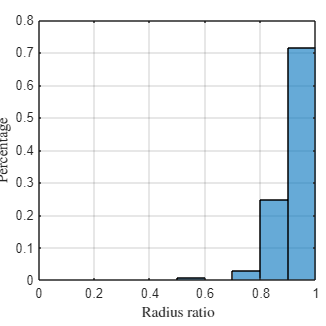

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on
exportgraphics(gca,'SquareLargeHole-MeshToolboxQualityDefault.pdf','ContentType','vector');

## Example 2: Hmax

### Mesh Generation 

mesh = generateMesh(model, GeometricOrder = "linear", Hmax=0.03);
nodes = mesh.Nodes; elements =mesh.Elements;

### Figure Mesh

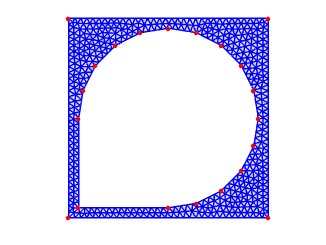

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on
plot(nodes_geo(1, :), nodes_geo(2, :), 'r.', MarkerSize = 10);

axis equal off

exportgraphics(gca,'SquareLargeHole-MeshToolboxHmax.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

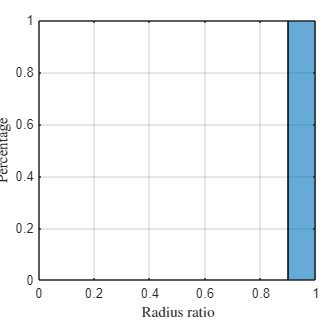

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on
exportgraphics(gca,'SquareLargeHole-MeshToolboxQualityHmax.pdf','ContentType','vector');

## Example 3: Hvertex

### Mesh generation and Figure

mesh = generateMesh(model, GeometricOrder = "linear", ...
    Hvertex = {2,0.025}, Hgrad=1.1);
nodes = mesh.Nodes; elements =mesh.Elements;

### Figure Mesh

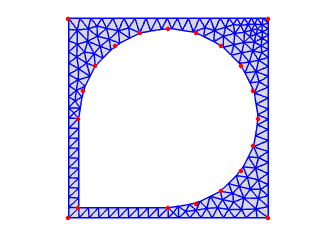

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on
plot(nodes_geo(1, :), nodes_geo(2, :), 'r.', MarkerSize = 10);

axis equal off
exportgraphics(gca,'SquareLargeHole-MeshToolboxHvertex.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

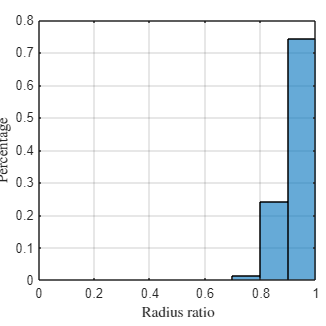

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on
exportgraphics(gca,'SquareLargeHole-MeshToolboxQualityHvertex.pdf','ContentType','vector');

## Example 4: Hedge

### Mesh Generation 

mesh = generateMesh(model, GeometricOrder = "linear", ...
    Hedge = {3,0.01}, Hgrad=1.1);
nodes = mesh.Nodes; elements =mesh.Elements;

### Figure Mesh

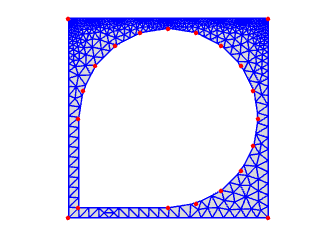

figure;
patch('Faces',elements','Vertices',nodes','FaceColor',[0.85, 0.85, 0.85], ...
    'EdgeColor','b');

hold on
plot(nodes_geo(1, :), nodes_geo(2, :), 'r.', MarkerSize = 10);

axis equal off
exportgraphics(gca,'SquareLargeHole-MeshToolboxHedge.pdf','ContentType','vector');

### Figure Mesh Quality Analysis

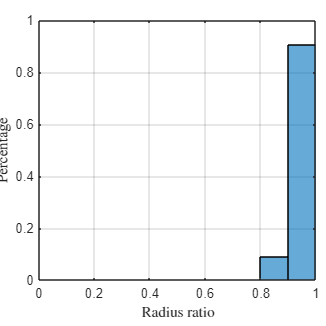

xs=nodes(1,:);ys=nodes(2,:);
t1=elements(1,:);t2=elements(2,:);t3=elements(3,:);
la=hypot(xs(t2)-xs(t1), ys(t2)-ys(t1));
lb=hypot(xs(t3)-xs(t1), ys(t3)-ys(t1));
lc=hypot(xs(t3)-xs(t2), ys(t3)-ys(t2));
rho=(lc+lb-la).*(lc+la-lb).*(la+lb-lc)./ (la.*lb.*lc);

figure;
histogram(rho,0:0.1:1,'Normalization','probability');
set(gcf,'Position',[230 250 400 400]) ;
set(gca,'Position',[0.12 0.14 0.85 0.8]);
xlim([0 1]);
xlabel('Radius ratio','interpreter','latex');
ylabel('Percentage','interpreter','latex');
grid on
exportgraphics(gca,'SquareLargeHole-MeshToolboxQualityHedge.pdf','ContentType','vector');